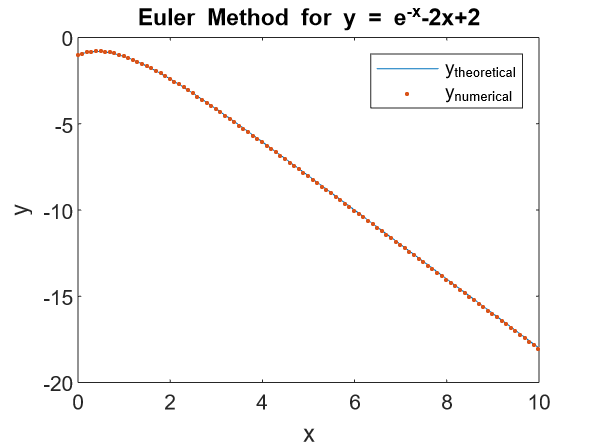

clc
clear

h = 0.1; n = 100;

yNumerical = zeros(1,n); yNumerical(1) = -1;
x(1) = 0; x = x(1):h:x(1)+h*n;
yDerivative = zeros(1,n);

syms X Y;
myFunction = -2*X-Y;
yTheoretical = -3.*exp(-x)-2.*x+2;


for i=1:n
    x(i+1) = 0.1*i;
    yDerivative(i) = subs(myFunction, [X,Y], [x(i),yNumerical(i)]);
    yNumerical(i+1) = yNumerical(i) + h*yDerivative(i);
end

error = yTheoretical - yNumerical;
errorPercentage = error./yTheoretical;

plot(x,yTheoretical,x,yNumerical,'.')
title("Euler Method for y = e^{-x}-2x+2")
xlabel("x"), ylabel("y")
legend("y_{theoretical}","y_{numerical}")